# Map Extension Algorithms and 3D Visualization

The DrivingScenarioDesigner APP can be used to extend the default map in MOBATSim. The intuitive and user-friendly interface of the APP makes it quite easy to define new roads segments. However, it should be consistent with the MOBATSim structure because later it needs to be converted to the MOBATSim Map Format for the simulation. In this documentation, we will go through the structural differences, coordinate transformations and the details regarding the conversion algorithm. After the simulation, the logged simulation data will be converted back to OPENDrive, so that the simulation can be visualized using the Bird's Eye Scope or the Unreal Engine 4 interface of the DrivingScenarioDesigner APP.

# Using the DrivingScenarioDesigner APP for MOBATSim

## Loading the MOBATSim Map

This data file can be changed and saved from drivingScenarioDesigner, which is used to extend the map using the OPENDrive format.

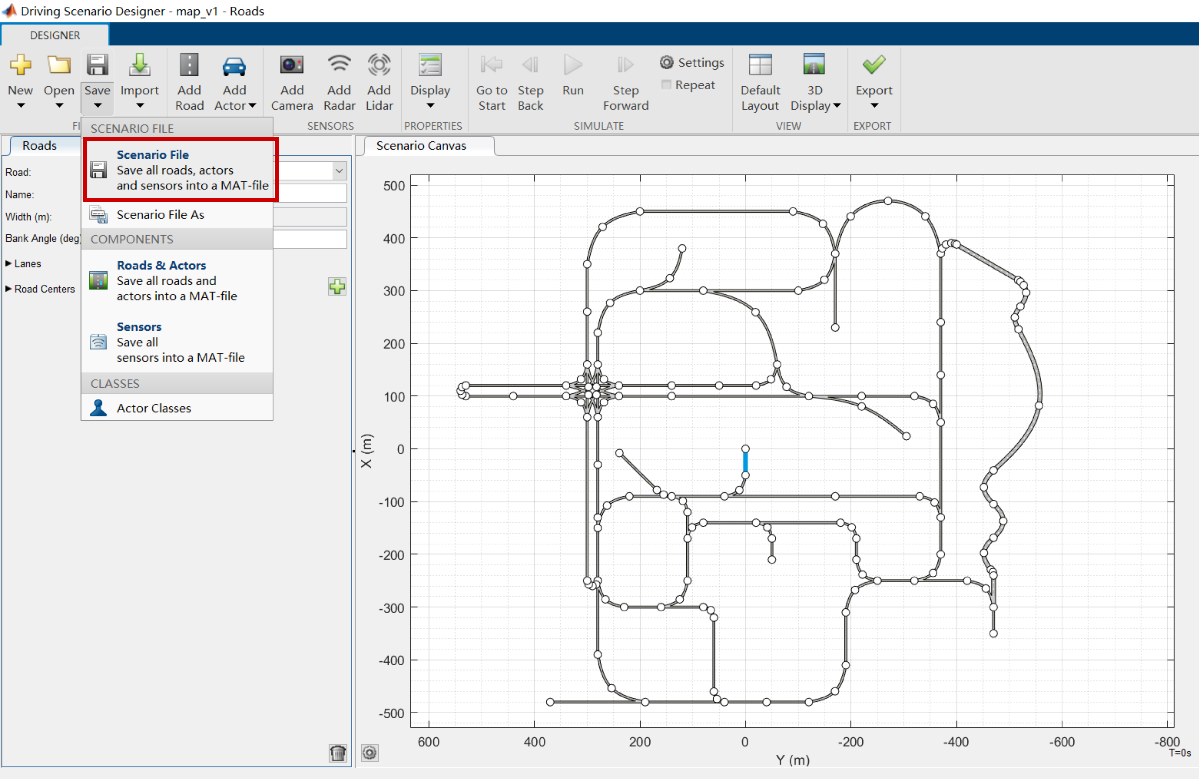

Then load the data file from original map, which is got from *src/Load Data/Load Data/load_mobatkent.m*. Because when the map is converted from `drivingScenarioDesigner`, the sequence of the waypoints might be different and this is especially important since the intersection waypoints are hard-coded according to their id numbers. So we will need to put them into the right sequence in the conversion algorithm, so that the extension waypoints start after the original Mobatkent map waypoints.

## Extending the MOBATSim Map

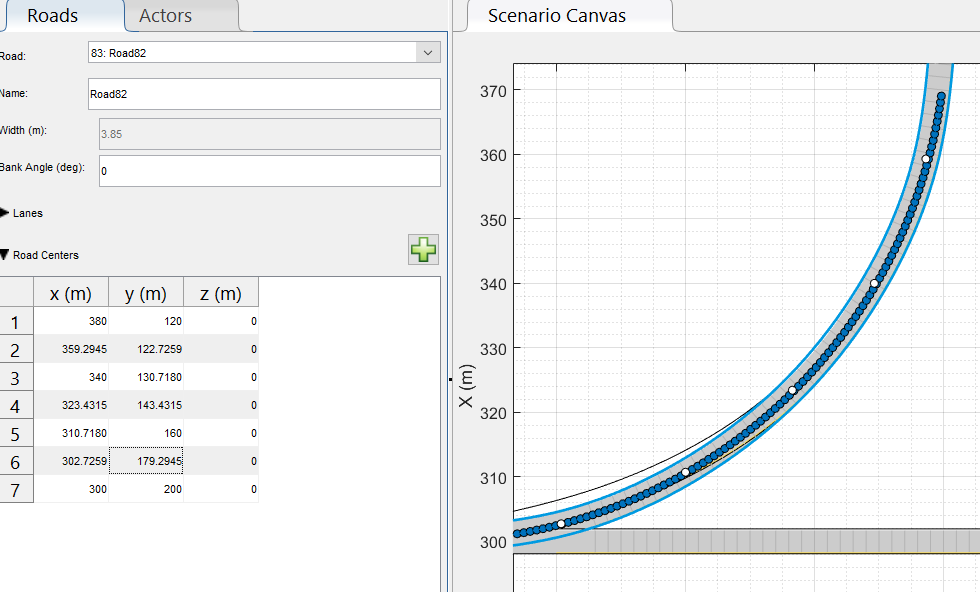

## Saving the MOBATSim Map as a Scenario File

# Loading the Map in MOBATSim from a Scenario File

This algorithm is mainly in *src/Scripts/Load Data/map_v1/map_extend_v1.m*.

These two *.mat* file is loaded in *src/Scripts/Load Data/map_v1/map_extend_v1.m*. If there is another version of the extended map, just change the *src/Scripts/Load Data/map_v1/map_v1.mat* to another one.

First, load the data file which include the coordinate of several points of each road section.

Initialize the arrary for road information which is the same form of *src/Scripts/Load Data/load_Mobatkent.m*.

Next, according to the information of above two loaded data file,  the algorithm transfer points coordinate to the information that we need, the detailed comment please find in *src/Scripts/Load Data/map_v1/map_extend_v1.m.*

## Coordinate Transformation - OPENDrive to MOBATSim

Placeholder**

## Coordinate Transformation - MOBATSim to OPENDrive

To get the lane numbers we need to check them from the DSD file. In a future release, the lane numbers might be added into the MOBATSim Map data structure.

Now all the required information for the simulation to run has been loaded and available for the plotting, pathfinding algorithms and vehicles in MOBATSim. The helper functions required to realize the above tasks are explained in detail below.

## Helper Functions

There are four helper functions used in *src/Scripts/Load Data/map_v1/map_extend_v1.m*:

### 1- `convertBackToMOBATSimfromAPP`

Outputs road edges as an array. Calculating the rotation center for the curved road is an important part of this function:

The angle is calculated in Polar coordinate

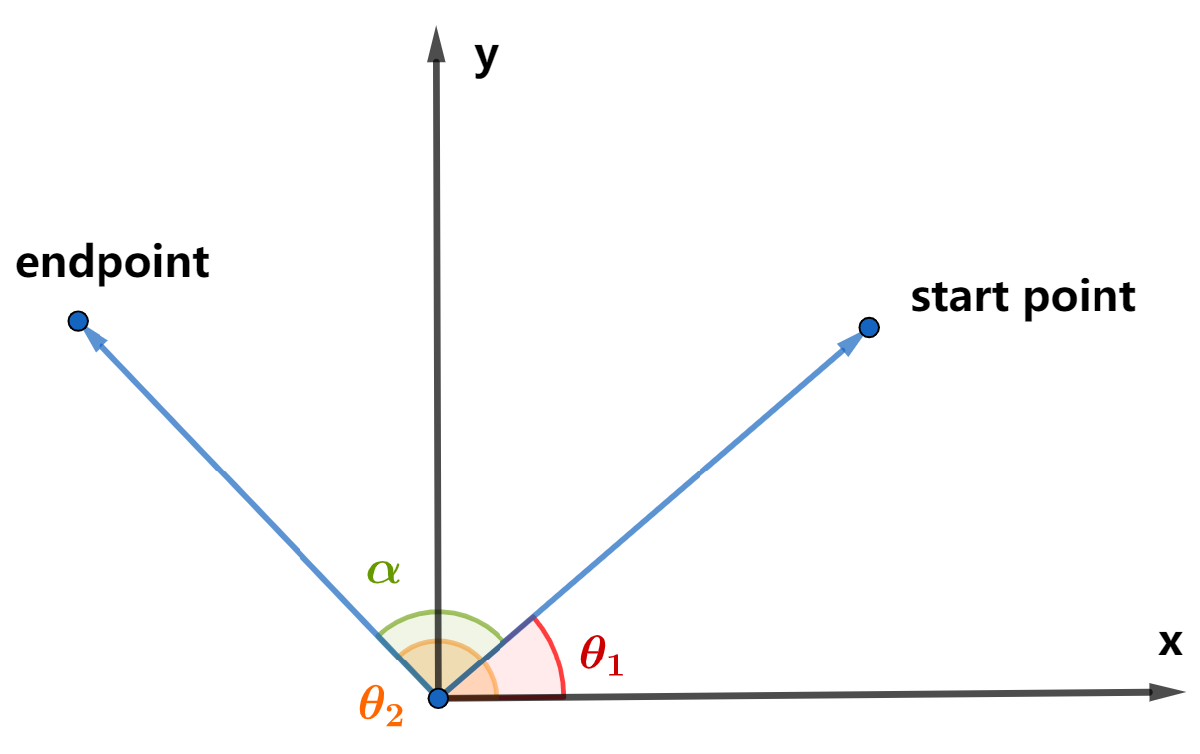


$$\alpha =\theta_2 -\theta_1$$


The angle is calculated in `drivingScenarioDesigner` coordinate, but in MOBATSim, the range of angle is $\left\lbrack -\pi ,\pi \right\rbrack$, so we should make sure the result is not outside of the range:

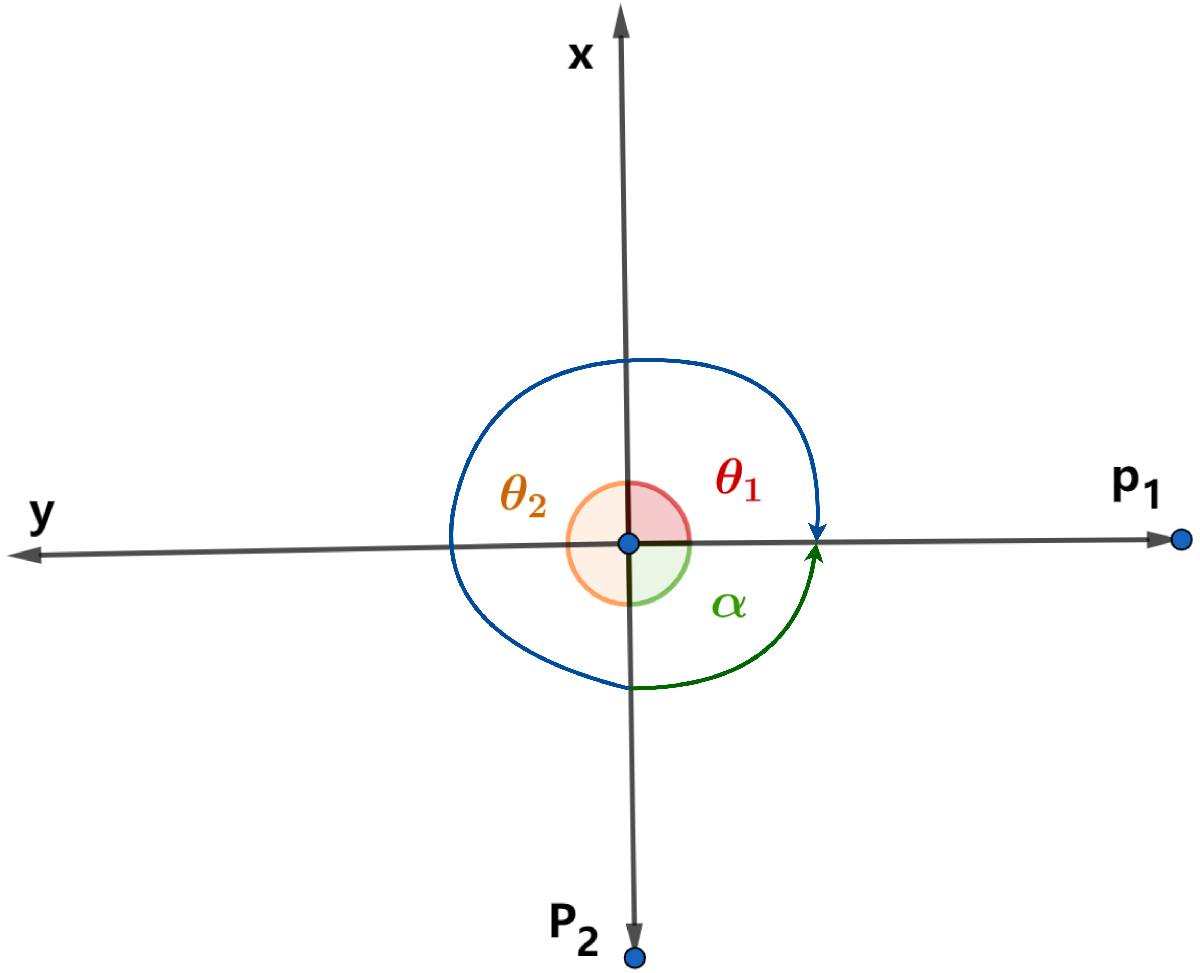

in the figure above, $p_2$ is start point, $p_1$ is endpoint, the angle is counterclockwise. In `drivingScenarioDesigner` coordinate, $\theta_2 =\pi$, $\theta_1 =-\frac{\pi }{2}$, $\alpha =\theta_2 -\theta_1 =\frac{-3\pi }{2}$ , which is outside of the range. so the final result is: $\alpha =\alpha +2\pi =\frac{\pi }{2}$.

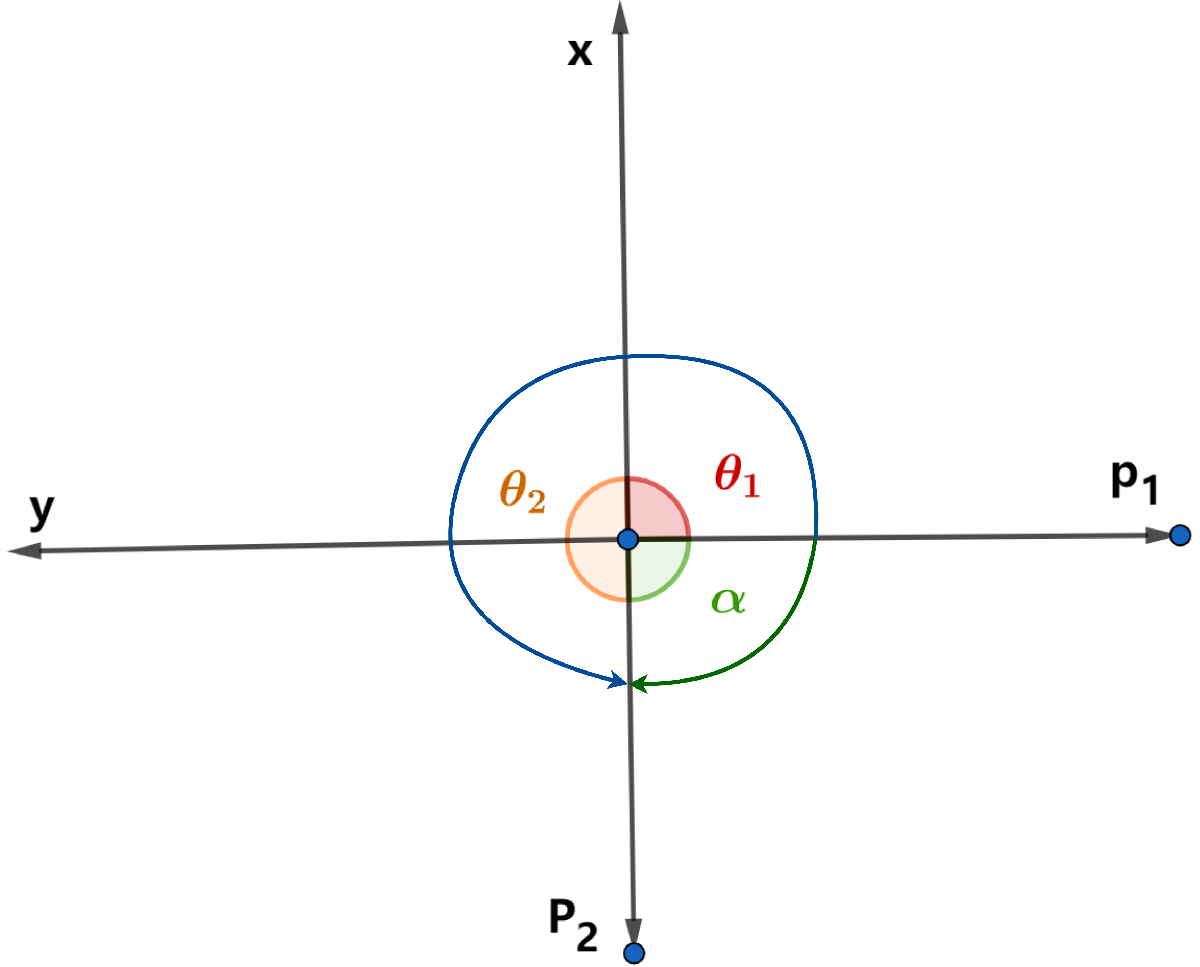

in the figure above, $p_1$ is the start point, $p_2$ is the endpoint, the direction of the rotation is clockwise. In the drivingScenarioDesigner coordinate system, $\theta_2 =\pi$, $\theta_1 =\frac{-\pi }{2}$, $\alpha =\theta_2 -\theta_1 =\frac{3\pi }{2}$, which is not in the range. So the final result is: $\alpha =\alpha -2\pi =\frac{-\pi }{2}$.

### 2- Circle_center

Calculates the circle center of the curved road section, which is used in the first function.

### 3- Order_sequence

Puts the points in the extended map into the same order as the original map.

### 4- Route_LaneNumber

Finds the number of the lane for the corresponding road.

The workflow of this function is shown below:

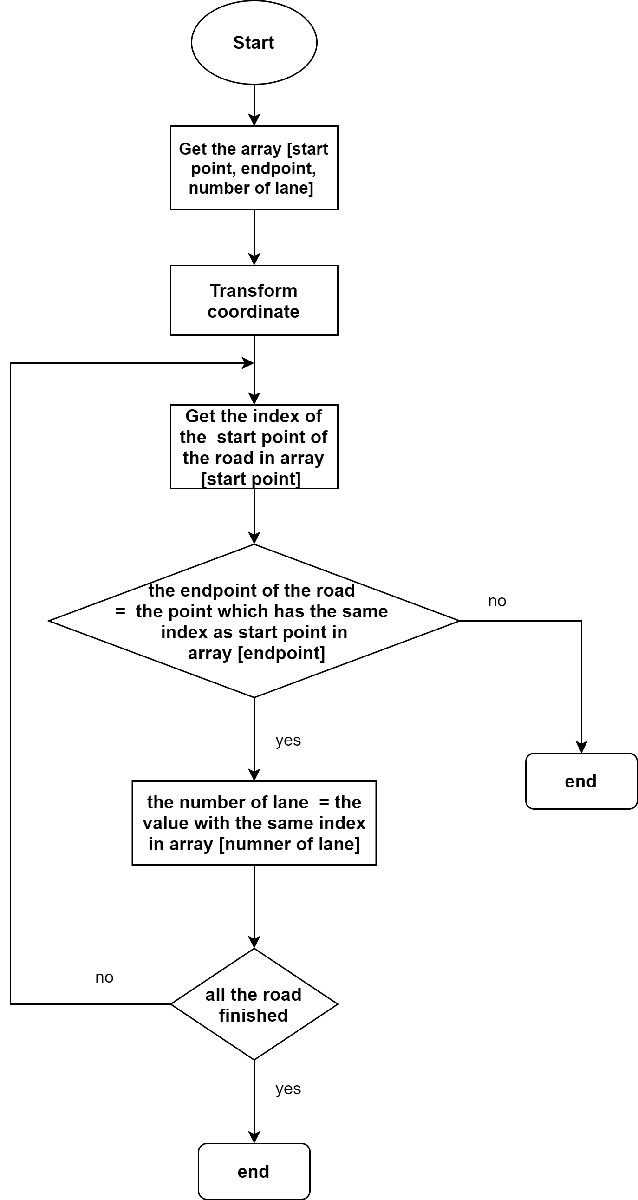

For other details in this algorithm, you can check the comment of "map_extend_v1.m"

If you just run "map_v1/map_extend_v1.m", there are four output arrays,:

When you make some changes, don't forget to check if the above output is correct.

The final output of the *src/Scripts/Load Data/map_v1/map_extend_v1.m* is the form shows below:

% waypoints = [x,0,-y];
% connections_translation = [startpoint, endpoint, speed];% the straight road section in the map
% connections_circle = [startpoint, endpoint, radian, circleCenter_x,0,-circleCenter_y, speed];% the curved road section in the map
% Route_LaneNumber = [Route_id, laneNumber] % lane number of the corresponding route

Next, just add the below line in *src/Scripts/Load Data\load_Mobatkent_from_opendrive.m*

% run map_extend_v1.m

Next, load extended map in load map section in *src/Scripts/prepare_simulator.m* instead of the orignal one.

% %% Load the Map
% switch mapName  
%     case 'Mobatkent'
%         %[mapName, waypoints, connections_circle, connections_translation, ...
%         %  startingNodes, brakingNodes, stoppingNodes, leavingNodes] = load_Mobatkent();
%         [Route_LaneNumber, waypoints, connections_translation, connections_circle, ...
%           startingNodes, brakingNodes, stoppingNodes, leavingNodes] = load_Mobatkent_from_opendrive();%load extended map
%     case 'Highway'
%         open_system('Platoon_Event')
%         return
%     
%     case 'Crossmap'
%         [Route_LaneNumber, mapName, waypoints, connections_circle, connections_translation, ...
%           startingNodes, brakingNodes, stoppingNodes, leavingNodes] = load_Crossmap();             
% end

Finally, run "prepare_simulator.m", you can get the map in the simulation.

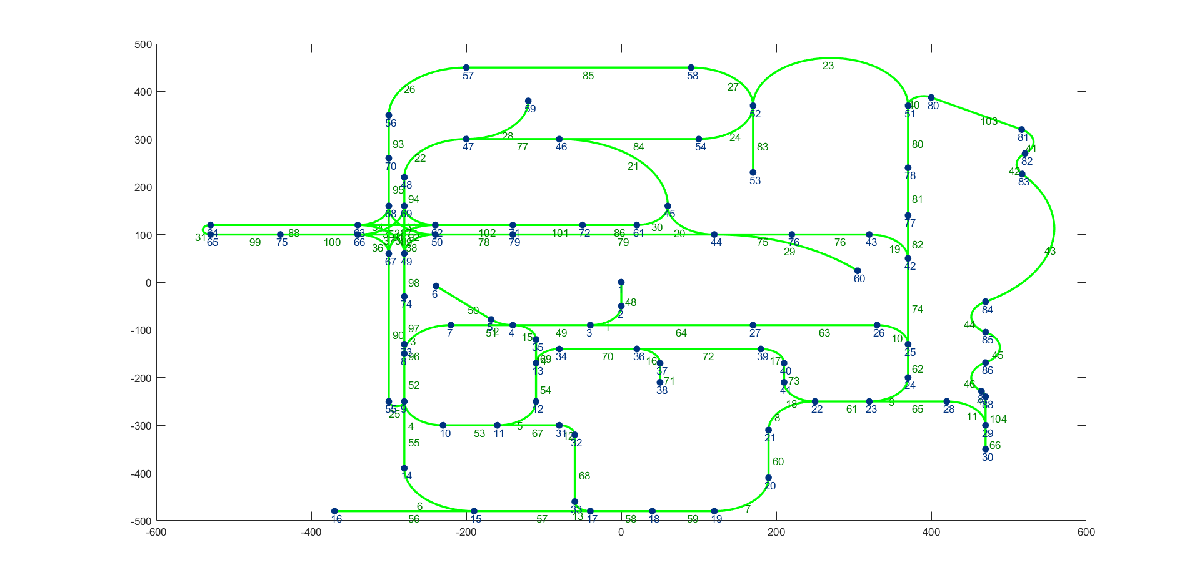

# Road Conversion Algorithm - MOBATSim to OPENDrive

An automatic algorithm for converting the MOBATSim Map directly into OPENDrive format will be developed soon. At the moment, the MOBATSim Map is redrawn in the drivingScenarioDesigner APP and it is saved after every extension.

# MATLAB function for map information exported from drivingScenarioDesigner

This script shows how to export the map information file "scenario_map_v1.m" of the scenario from drivingScenarioDesigner for 2D and 3D visualization.

- First, open app `Driving Scenario Designer`, and click button "open"  to open *scr\Scripts\Load Data\map_v1\map_v1.mat*  in the app.

     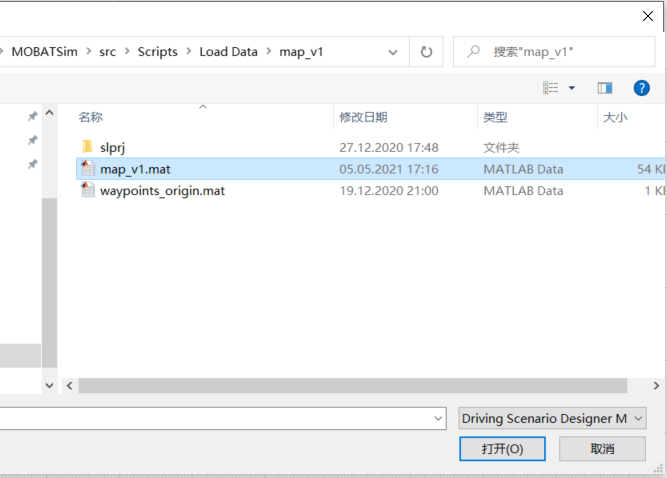

      2. The left side are the parameters of the chosen road section. If the road needs to be changed from single lane to double lane, just change the `Number of Lanes` from 1 to 2.

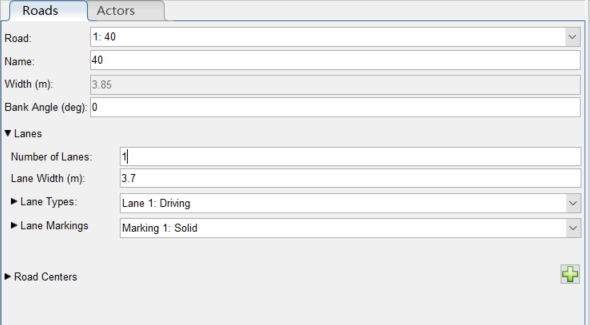

3. Click "Export", and click "MATLAB Function".

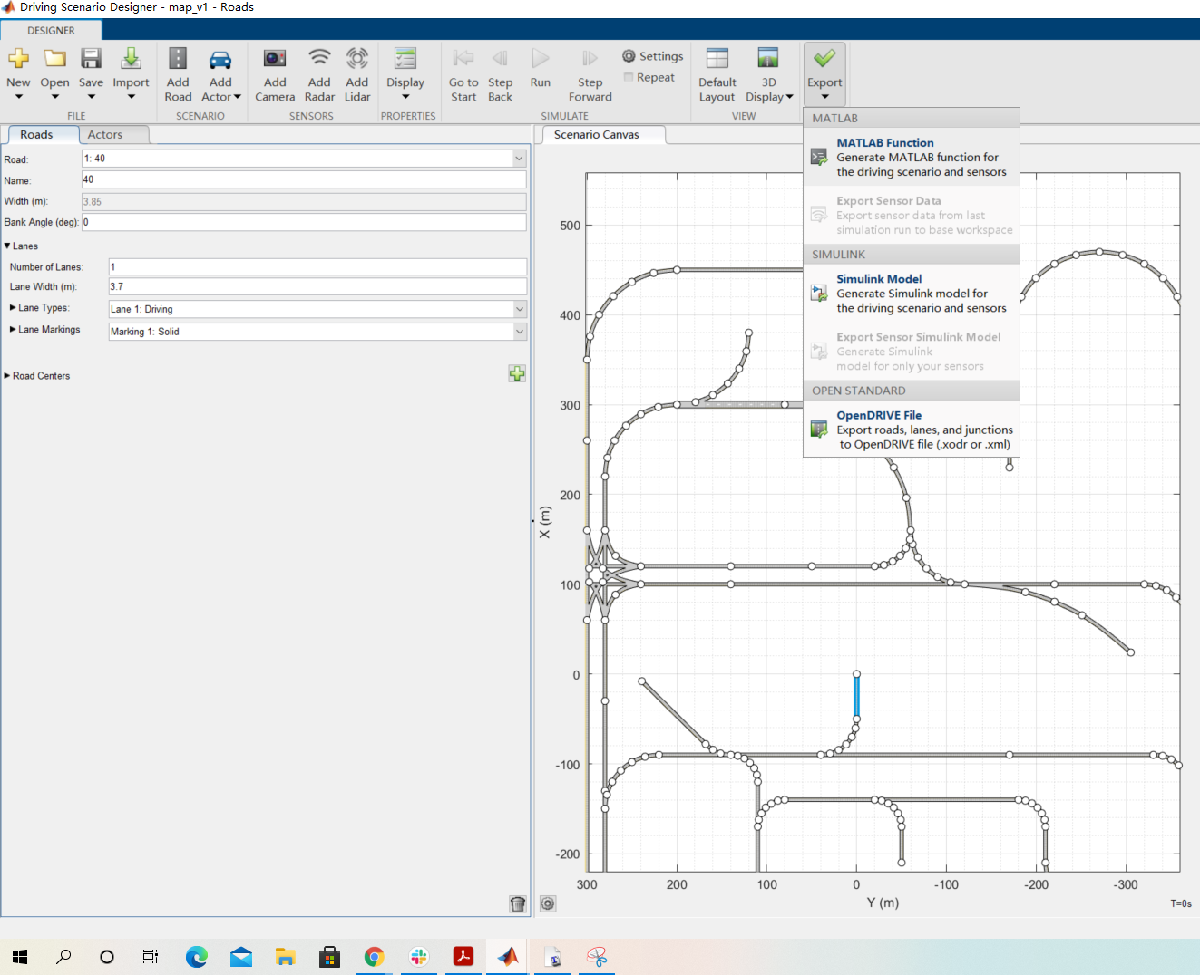

The exported function of the scenario contains the data of the map for visualization.

% function scenario = map_v1()
% % createDrivingScenario Returns the drivingScenario defined in the Designer
% 
% % Generated by MATLAB(R) 9.9 (R2020b) and Automated Driving Toolbox 3.2 (R2020b).
% % Generated on: 21-May-2021 22:17:45
% 
% % Construct a drivingScenario object.
% scenario = drivingScenario;
% 
% % Add all road segments
% roadCenters = [0 0 0;
%     -50 0 0];
% laneSpecification = lanespec(1, 'Width', 3.7);
% road(scenario, roadCenters, 'Lanes', laneSpecification, 'Name', '40');
% ......
%     

4. Save the function in folder *src/Scripts/Load Data/map_v1* as a `.m` file *map_v1.m*, and change the name of the function to the same with file function.

% function scenario = scenario_map_v1()

5. If one of the roads needs to be shifted for a distance, just change the coordinate of the corresponding `roadCenters`. This change is only for visualization, it doesn't change the MOBATSim map.

% roadCenters = [300 -100 0;
%     300 80 0];
% roadCenters(:,1) = roadCenters(:,1)+1.85;% add 1.85 to x to shift the road
% laneSpecification = lanespec(2, 'Width', 3.7);
% road(scenario, roadCenters, 'Lanes', laneSpecification, 'Name', 'Road36');

6. The map is loaded in "run_Bird_eye_view.m" and "openScenarioInApp.m" for 2D and 3D visualization with following:

% MOBATKent_Scenario = scenario_map_v1();

7. If the map is newly updated or changes, just repeat the above procedure to update the scenario for visualization.